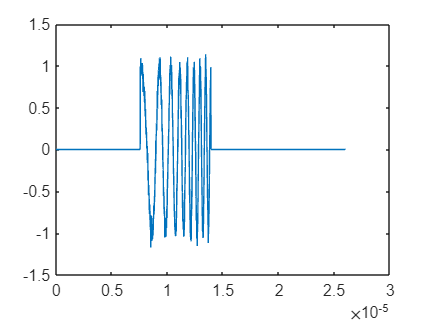

clear
clc

fs = 1e8;
f0 = (rand()*21+2)*1e5; %f0 in [2e5,23e5]Hz
f1 = (rand()*21+2)*1e5; %f1 in [2e5,23e5]Hz
t1 = (rand()*10+5)*1e-6; %持续时间5~15us
t_tmp = 0:1/fs:t1;
chrp = chirp(t_tmp,f0,t1,f1,'complex'); %生成chirp信号
chrp = awgn(chrp,20);
t0 = rand()*(1e-5); %开始时间0~10us
n0 = floor(t0 * fs) + 1; %计算开始时间采样点序号
n1 = n0 + length(chrp)-1;
real_fm = (f1-f0)/t1;

t = 0:1/fs:(26e-6); %时间序列 26us
x = zeros(1,length(t));
x(n0:n1) = x(n0:n1)+chrp;
% plot(t,x);

% stft(x,fs,"Window",hann(40,'periodic'));

[pafmag,delay,doppler] = pambgfun(x,fs);
coef = -doppler(ceil(length(doppler)/2))*fs;
cut_len = ceil(length(delay)/4);
pafmag = pafmag(:,cut_len:end+1-cut_len);
delay = delay(cut_len:end+1-cut_len);
% imagesc(delay,doppler,pafmag)
% axis xy
% xlabel('Delay (sec)')
% ylabel('Doppler Shift (Hz)')
% colorbar

theta = 1:0.5:179;
[R,xp] = radon(pafmag,theta);
% imshow(R,[],'Xdata',theta,'Ydata',xp,'InitialMagnification','fit')
% xlabel('\theta (degrees)')
% ylabel('x')
% colormap(gca,hot), colorbar
row_index = ceil(length(xp)/2);
mag_af = R(row_index,:);
indmax=find(diff(sign(diff(mag_af)))<0)+1;
ind_candidate = indmax(mag_af(indmax)>250);
ang = 90-theta(ind_candidate);
fm = coef*tan(ang/180*pi);

a = 2/pi*acot(-fm/(fs^2));
y = myfrft(x',a)';
u=linspace(-fs/2,fs/2-1,length(y));
% figure;
% plot(u,abs(y));
u_index = y>(max(y)/2);
u_mean = mean(u(u_index));
fh_predict=abs(u_mean*csc(a*pi/2));%估计的中心频率
fh_real = (f1+f0)/2;